# Apuntes de Clase - Esperanza Matemática

Herramientas Matemáticas para el Manejo de la Información

Sesión 7 - 29 de septiembre de 2018

# Distribución de datos reales

## Tiempos entrearribos de una traza capturada en los laboratorios de Bellcore

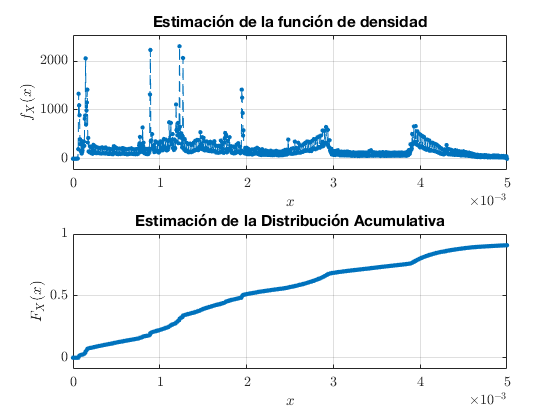

datos = load('BCpAug89.TL');
tiempos = datos(:,1);
tiemposentrearribos = diff(tiempos);
pdfcdfcontinua(tiemposentrearribos,0,0.005);

## Datos de la aceleración de la gravedad capturados con el acelerómetro de un teléfono móvil

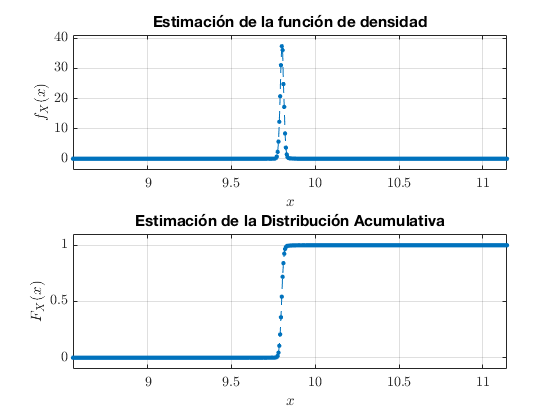

load('datosacelerometro.mat');
pdfcdfcontinua(aceleracionz)

## Frecuencias cardiacas instantáneas de un paciente de la European Database

filename = 'rr.txt';
fileID = fopen(filename);
A = textscan(fileID,'%s %s %f %s %s','Delimiter','\t');

Error using textscan
Invalid file identifier. Use fopen to generate a valid file identifier.

fclose(fileID);
rrinterval = cell2mat(A(3)); % Intervalos R-R en segundos
datos = 60./rrinterval; % Frecuencias instantáneas en bpm
pdfcdfcontinua(datos)

## Ejercicio en Clase

Obtenga la distribución de las frecuencias cardiacas instantáneas de cinco pacientes de la *European Database.*

## Estudiantes que resolvieron correctamente el ejercicio

Fabián Barreto

Gabriel González

Andrés Mesa

# Esperanza Matemática

Sea $X$ una variable aleatoria (continua o discreta):


$$X:\Omega \to \mathbb{R}$$


con función de densidad de probabilidad:


$$f_X(x)$$


y sea $g(x)$ una función de la variable aleatoria $X$. La esperanza matemática se define como el producto interno de $g(x)$ y  $f_X(x)$:


$$E[g(x)]=\langle g(x), f_x(x)\rangle=\int_{-\infty}^{\infty}g(x)f_X(x)\text{dx}$$


## Esperanza Matemática de una constante: $A$


$$E[A]=\langle A, f_x(x)\rangle=\int_{-\infty}^{\infty}Af_X(x)\text{dx}=A\int_{-\infty}^{\infty}f_X(x)\text{dx}=A$$


## Esperanza Matemática de la variable aleatoria $X$


$$E[X]=\langle x, f_x(x)\rangle=\int_{-\infty}^{\infty}xf_X(x)\text{dx}=\text{media, valor promedio o primer momento} $$


## Esperanza Matemática de la variable aleatoria $X^2$


$$E[X^2]=\langle x^2, f_x(x)\rangle=\int_{-\infty}^{\infty}x^2f_X(x)\text{dx}=\text{segundo momento} $$


## Esperanza Matemática de la variable aleatoria $X^n$, con $n \in \mathbb{R}$


$$E[X^n]=\langle x^n, f_x(x)\rangle=\int_{-\infty}^{\infty}x^nf_X(x)\text{dx}=\text{momento n} $$


## Esperanza Matemática de $(X-E[X])^2$


$$E[(X-E[X])^2]=\langle (x-E[X])^2, f_x(x)\rangle=\int_{-\infty}^{\infty}(x-E[X])^2f_X(x)\text{dx}$$



$$E[(X-E[X])^2]=\int_{-\infty}^{\infty}x^2f_X(x)\text{dx}-2E[X]\int_{-\infty}^{\infty}xf_X(x)\text{dx}+E[X]^2\int_{-\infty}^{\infty}f_X(x)\text{dx}$$



$$E[(X-E[X])^2]=E[X]^2-2E[X]E[X]+E[X]^2$$



$$E[(X-E[X])^2]=E[X^2]-E[X]^2 = \text{varianza} = \sigma_X^2$$


A $\sigma_X$ se le da el nombre de desviación estándar.

## Ejercicio en Clase

Calcule la media de la distribución uniforme continua:


$$U:\Omega \to \mathbb{R}$$



$$U\sim \mathcal{U}(a,b)$$



$$f_U(u)=\begin{cases}0 & u<a \\ \frac{1}{b-a} & a \leq u \leq b \\ 0 & u>b
\end{cases}$$


## Estudiantes que resolvieron el ejercicio

David Millán

Brayan Bermúdez

Jose Ricardo Castillo

Oswaldo Granados

## Ejercicio en Clase

Calcule la varianza de la distribución uniforme continua

## Estudiantes que resolvieron correctamente el ejercicio

Laura Manrique

Juan Moreno

Juan Carlos Parra